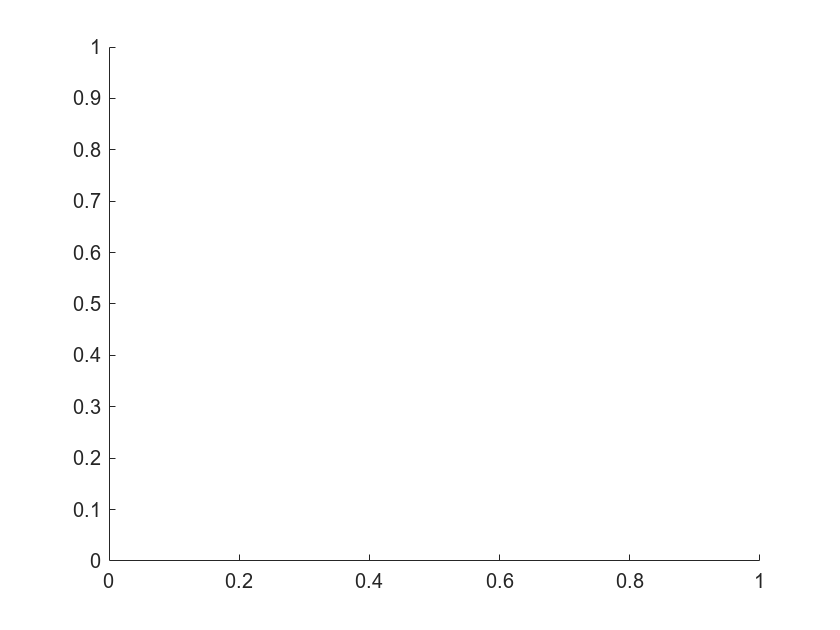

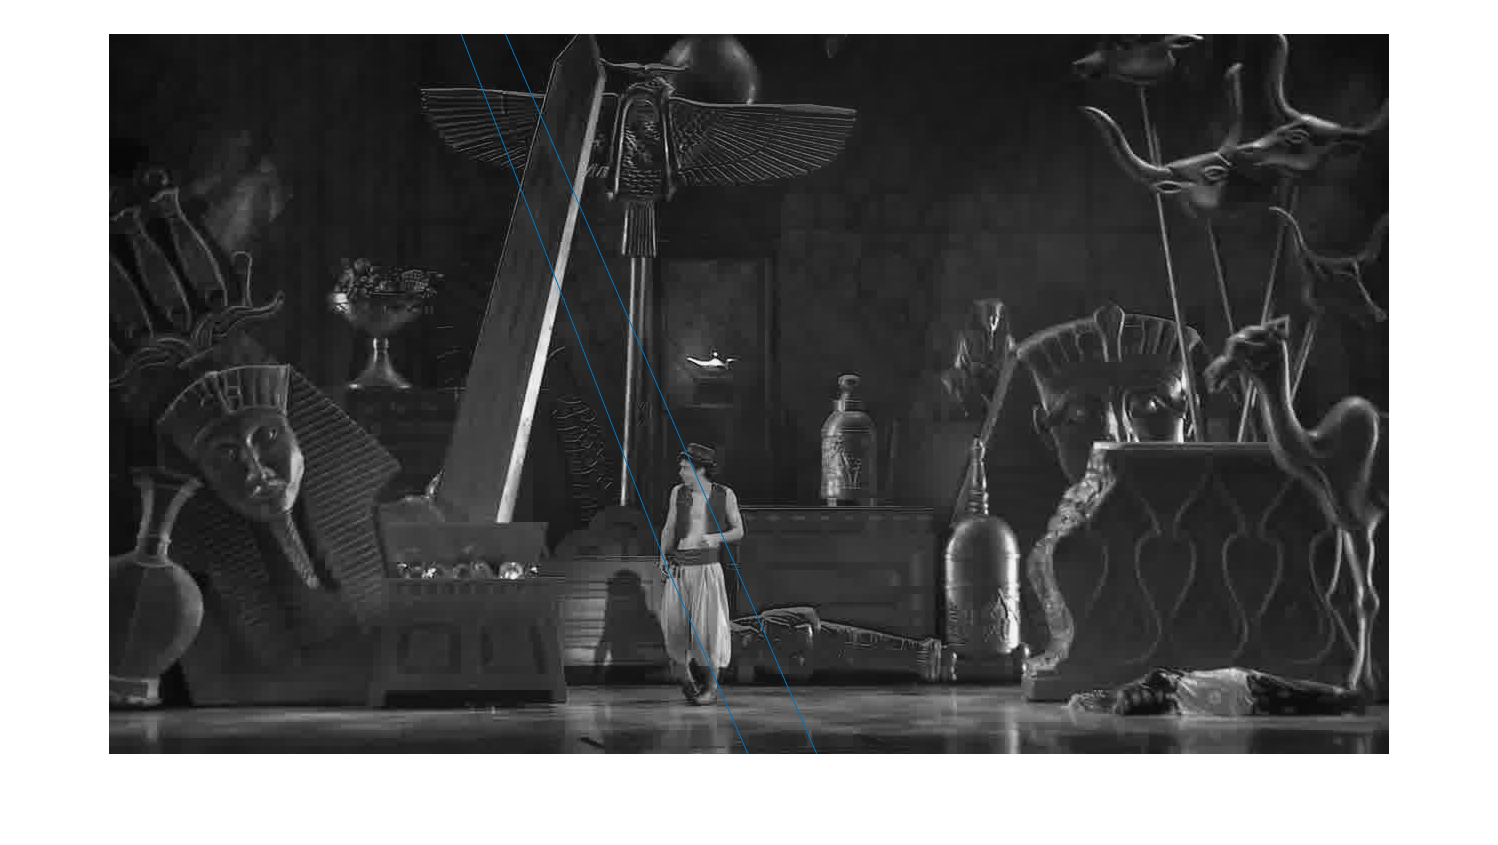

%videoNames =dir("TinyTLP\");
videoNames = {'Alladin','PolarBear1'};
nFrames = 100;
OverlappingRates = zeros([size(videoNames,2), nFrames]);
for i=1:(size(videoNames)+1)
    name = videoNames{i};
    OverlappingRates(i,:) = kalman(name,nFrames);
    
end


%%



function [ORatio] = kalman(nom_fitxer, nIt)

    close all
    hold off

    path1 = strcat('./TinyTLP/', nom_fitxer);
    path11 = strcat(path1,'/groundtruth_rect.txt');
    path2 = strcat(path1,'/img/*.jpg');

    BB = importdata(path11);
    Idir = dir(path2);

    figure
    hold on % mantenim sempre oberta la mateixa figura



    filename = horzcat(Idir(1).folder,'/',Idir(1).name);
    I = imread(filename);
    B1 = BB(1,2:5);
    
    im_obje = rgb2gray(imcrop(I,B1));
    im_obj = im_obje(:,:,1);
    imshow(im_obj);
    
    ORatio = zeros(1,100);

    for i = 1:nIt
        filename = horzcat(Idir(i).folder,'/',Idir(i).name);
        I2 = imread(filename);

        im_esce = rgb2gray(I2);
        im_esc = im_esce(:,:,1);
        % SIFT
        kp_obj = detectSIFTFeatures(im_obj);
        kp_esc = detectSIFTFeatures(im_esc);

        [feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
        [feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

        pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold',2);

        m_kp_obj = kp_obj(pairs(:,1)); % agafem els millors punts
        m_kp_esc = kp_esc(pairs(:,2));

        % Ransac
        if (m_kp_obj.Count > 3) && (m_kp_esc.Count > 3)
            [T] = estimateGeometricTransform2D(m_kp_obj,m_kp_esc, "affine");
        
            Bi = BB(i,2:5);
            
            fo = Bi(4);
            co = Bi(3);

            box = [1,1; co,1; co,fo; 1,fo; 1,1];

            nbox = transformPointsForward(T,box);
            B2 = [nbox(1,1),nbox(1,2),Bi(3),Bi(4)];
            ORatio(1,i) = bboxOverlapRatio(Bi,B2);

            imshow(im_esc)
            hold on
            line(nbox(:,1),nbox(:,2));
            drawnow
        end
    end
end

function [minx, miny] = topLeftCoordinate(centralPoint, width, height)
    minx = centralPoint(1) - width/2;
    miny = centralPoint(2) - height/2; 
end
%% 
% Comentari: Hue no funciona, hem provat el video Hideway amb el kalman original 
% però canviant el rgb2gray a rgb2hsv ( i agafant la component hue). No funciona 
% ja que es perd molta informació de l'imatge: (comparar captura original, gray 
% i hsv).